# 距离多普勒算法

**算法简介**

在**原始SAR信号空间**中，一个地面目标点的**反射回波数据**占据了一块区域(**多个像素点**)，严重的是，目标点的**展宽扩散**就会污染影响相邻的目标点，造成**散焦**，视觉上就给人模糊不清的感觉。**距离多普勒算法**(RDA)通过距离和方位上的**频域操作**(对原始SAR回波数据进行压缩，从而达到聚焦的目的)，达到了高效的模块化处理要求，同时又具有了一维操作的简便性，RDA算法根据距离和方位上的大尺度时间差异，在两个一维操作之间使用距**离徙动校正**(RCMC)，对距离向和方位向进行了近似的分离处理，使得距离向压缩和方位向压缩可以解耦。

**算法概述**

                         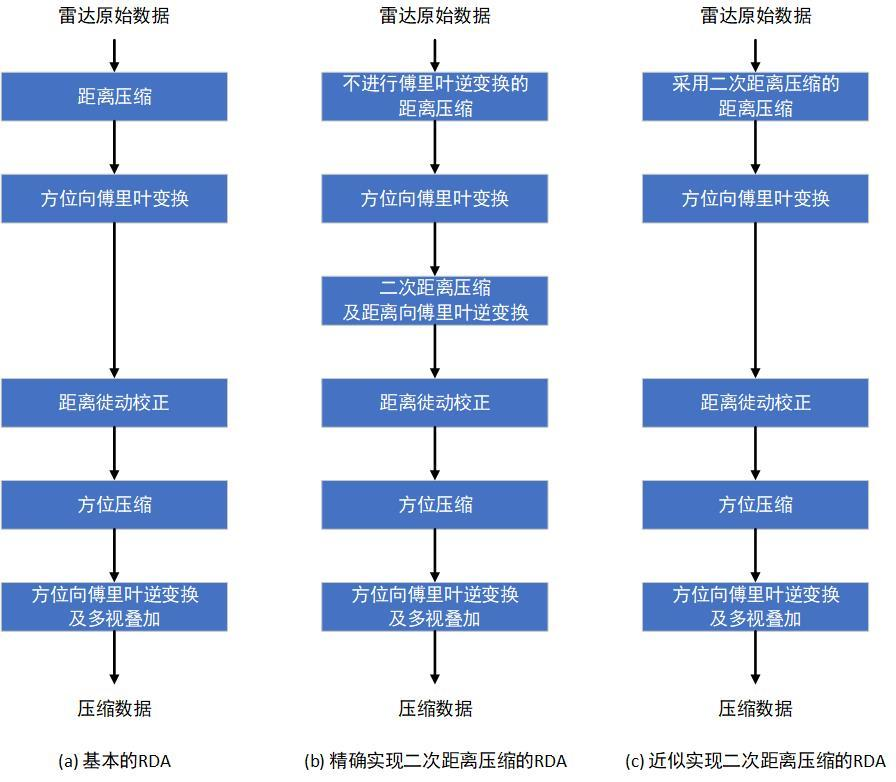

(a)给出的是适合小斜视角及短孔径下的基本RDA处理算法，(b)是斜视处理所需的二次距离压缩改进算法，其中二次距离压缩为二维频域中的精确实现，(c)是二次距离压缩的近似距离频域实现，与(b)相比，其效率较高。

**仿真参数**

**距离向参数：**

                      √ 景中心斜距        $R(\eta_c)$       R_eta_c        20               $km$

                      √ 发射脉冲时宽    $T_r$             Tr                  2.5              $\mu s$

                      √ 距离向调频率    $K_r$             Kr                 20e+12       $Hz/s$

                      √ 距离信号带宽    $B_\omega$            Bw               $|K_r|T_r$          $Hz$

                      √ 距离过采样率    $\alpha_{os,r}$          alpha_os_r   1.2                \

                      √ 距离向采样率    $F_r$             Fr                 $\alpha_{os,r}B_\omega$        $Hz$        

                      √ 距离线采样点数$N_{rg}$            Nrg               320              \

                         距离向分辨率    $\rho_r$             rho_r             2.7              $m$

**方位向参数：**

**                      √ **等效雷达速度    $Vr$            Vr                150                $m/s$

                      √ 电磁传播速度    $c$               c                  3e+8             $m/s$

                      √ 雷达工作频率    $f_0$              f0                 5.3e+9          $Hz$

                      √ 雷达工作波长    $\lambda$              lambda         $c/f_0$              $m$

                      √ 多普勒带宽       $\Delta f_{dop}$        Delta_f_dop  80                 $Hz$

                         目标照射时间    $T_a$            Ta                 **formula**         $s$

                         方位向调频率    $K_a$            Ka                **formula**        $Hz/s$

                      √ 方位过采样率    $\alpha_{os,a}$         alpha_os_a   1.25               \

                     √  方位向采样率    $F_a$            Fa                 $\alpha_{os,a}\Delta f_{dop}$      $Hz$

                      √ 距离线数           $N_{az}$           Naz               256                \

                         方位向分辨率    $\rho_a$            rho_a            1.7                $m$

**方位向参数：**

**                      √ **波束斜视角              $\theta_{sq,c}$   theta_sq_c    3.5&+21.9     $^{\circ}$

                      √ 波束中心穿越时刻    $\eta_c$     t_eta_c          -8.1&-49.7    $s$      

                         
$$\eta_c = -R(\eta_c)\sin\theta_(sq,c)/V_g
           = -R(\eta_c)\sin\theta_(r,c)/V_r$$


                      √ 多普勒中心频率      $f_{\eta_c}$      f_eta_c          320&1975    $Hz$  

                         
$$f_{\eta_c}=2V_s\sin\theta_{sq,c}/\lambda
               =2V_r\sin\theta_{r,c}/\lambda$$


由于是以上参数是机载C波段雷达仿真参数，故$\theta_{r,c}=\theta_{sq,c}$，$V_r=V_s=V_g$。

目标照射时间公式为：$T_a=0.886\frac{\lambda R(\eta_c)}{L_aV_g\cos\theta_{r,c}}$，方位向调频率公式为：$K_a=\frac{2V_r^2\cos^2\theta_{r,c}}{\lambda R(\eta_c)}$。除此之外，雷达到目标的最短距离为：$R_0=R(\eta_c)\cos\theta_{r,c}$，雷达的方位向3dB波束宽度为：$\theta_{bw}=\frac{\lambda\Delta f_{dop}}{2V_s\cos\theta_{r,c}}=0.886\frac{\lambda}{L_a}$，则实际天线长度为：$L_a=0.886\frac{2V_s\cos\theta_{r,c}}{\Delta f_{dop}}$。我们还可以得到在无孔径加权的情况下的距离分辨率$\rho_r=\frac{c}{2B_\omega}$和方位分辨率$\rho_a=\frac{L_a}{2}$。

**雷达原始数据**


$$s_0(\tau,\eta)=A_0
                        \omega_r\left(\tau-\frac{2R(\eta)}{c}\right)
                        \omega_a(\eta-\eta_c)
                        \exp\left\{ -j4\pi\frac{f_0R(\eta)}{c} \right\}
                        \exp\left\{ j\pi K_r\left(\tau-\frac{2R(\eta)}{c}\right)^2 \right\}$$


$T_a=0.886\frac{\lambda R(\eta_c)}{L_aV_g\cos\theta_{r,c}}$，$K_a=\frac{2V_r^2\cos^2\theta_{r,c}}{\lambda R(\eta_c)}$，$R(\eta)=\sqrt{R_0^2+V_r^2\eta^2}$，

$\omega_r\left(\tau-\frac{2R(\eta)}{c}\right)=rect\left(\frac{\tau-2R(\eta)/c}{T_r}\right)$，$\omega_a(\eta-\eta_c)=sinc^2\left[0.886\frac{\theta_{r,c}}{\theta_{bw}}\right]=sinc^2\left[0.886\frac{\arctan(V_g(\eta-\eta_c)/R_0)}{\theta_{bw}}\right]$

                      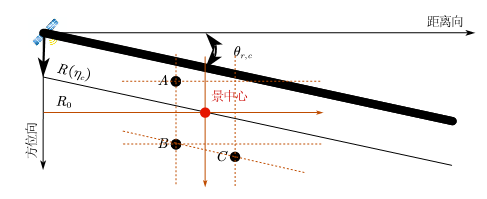

$\bullet$ 距离向和方位向的观测中心选取：距离向观测时间中心应该选为$2R(\eta_c)/c$，方位向观测时间中心应该选为$\eta_c$。这是因为雷达回波数据都以这两个时刻为中心分布，如此方能在原始雷达图像中观测到目标点数据。

$\bullet$ 目标点位置的设置：目标点的波束中心穿越时刻应该与景中心的波束中心穿越时刻相近，即目标点的波束中心穿越时刻斜距应该与景中心斜距相近，这样我们才能在有效的观测范围内观测到全部目标点。

$\bullet$ 距离徙动校正时距离向的观测中心选取：距离轴的中心应该选为$R_0=R(\eta_c)\cos\theta_{r,c}$。这是因为距离徙动校正后，目标数据点都会移动到自己的最近斜距处，若仍以$R(\eta_c)$作为距离轴的中心，则会导致距离徙动校正错误。

clc
clear
close all
%% 参数设置
%  已知参数--》距离向参数
R_eta_c = 20e+3;                % 景中心斜距
Tr = 2.5e-6;                    % 发射脉冲时宽
Kr = 20e+12;                    % 距离向调频率
alpha_os_r = 1.2;               % 距离过采样率
Nrg = 320;                      % 距离线采样点数
%  计算参数--》距离向参数
Bw = abs(Kr)*Tr;                % 距离信号带宽
Fr = alpha_os_r*Bw;             % 距离向采样率
Nr = round(Fr*Tr);              % 距离采样点数(脉冲序列长度)
%  已知参数--》方位向参数
c = 3e+8;                       % 电磁传播速度
Vr = 150;                       % 等效雷达速度
Vs = Vr;                        % 卫星平台速度
Vg = Vr;                        % 波束扫描速度
f0 = 5.3e+9;                    % 雷达工作频率
Delta_f_dop = 80;               % 多普勒带宽
alpha_os_a = 1.25;              % 方位过采样率
Naz = 256;                      % 距离线数
theta_r_c = [3.5,21.9]*pi/180;  % 波束斜视角
t_eta_c = [-8.1,-49.7];         % 波束中心穿越时刻
%{
t_eta_c = -R_eta_c*sin(theta_r_c(2))/Vr
%}
f_eta_c = [320,1975];           % 多普勒中心频率
%  计算参数--》方位向参数
lambda = c/f0;                  % 雷达工作波长
La = 0.886*2*Vs*cos(theta_r_c(1))/Delta_f_dop;               
                                % 实际天线长度
Fa = alpha_os_a*Delta_f_dop;    % 方位向采样率
Ta = 0.886*lambda*R_eta_c/(La*Vg*cos(theta_r_c(1)));
                                % 目标照射时间
R0 = R_eta_c*cos(theta_r_c(1)); % 最短斜距
Ka = 2*Vr^2*cos(theta_r_c(1))^2/lambda/R0;              
                                % 方位向调频率
theta_bw = 0.886*lambda/La;     % 方位向3dB波束宽度
%  参数计算
rho_r = c/(2*Fr);               % 距离向分辨率
rho_a = La/2;                   % 距离向分辨率
Trg = Nrg/Fr;                   % 发射脉冲时宽
Taz = Naz/Fa;                   % 目标照射时间
d_t_tau = 1/Fr;                 % 距离采样时间间隔
d_t_eta = 1/Fa;                 % 方位采样时间间隔
d_f_tau = Fr/Nrg;               % 距离采样频率间隔    
d_f_eta = Fa/Naz;               % 方位采样频率间隔
%  目标参数
%  设置目标点相对于景中心之间的距离
A_r =   0; A_a =   0;                                   % A点位置
B_r = -50; B_a = -50;                                   % B点位置
C_r = -50; C_a = +50;                                   % C点位置
D_r = +50; D_a = C_a + (D_r-C_r)*tan(theta_r_c(1));     % D点位置
%  得到目标点相对于景中心的位置坐标
A_x = R0 + A_r; A_Y = A_a;                              % A点位置
B_x = R0 + B_r; B_Y = B_a;                              % B点位置
C_x = R0 + C_r; C_Y = C_a;                              % C点位置
D_x = R0 + D_r; D_Y = D_a;                              % D点位置
NPosition = [A_x,A_Y;
             B_x,B_Y;
             C_x,C_Y;
             D_x,D_Y;];                                 % 设置数组
fprintf( 'A点坐标为[%+3.3f，%+3.3f]km\n', NPosition(1,1)/1e3, NPosition(1,2)/1e3 );

A点坐标为[+19.963，+0.000]km


fprintf( 'B点坐标为[%+3.3f，%+3.3f]km\n', NPosition(2,1)/1e3, NPosition(2,2)/1e3 );

B点坐标为[+19.913，-0.050]km


fprintf( 'C点坐标为[%+3.3f，%+3.3f]km\n', NPosition(3,1)/1e3, NPosition(3,2)/1e3 );

C点坐标为[+19.913，+0.050]km


fprintf( 'D点坐标为[%+3.3f，%+3.3f]km\n', NPosition(4,1)/1e3, NPosition(4,2)/1e3 );

D点坐标为[+20.013，+0.056]km


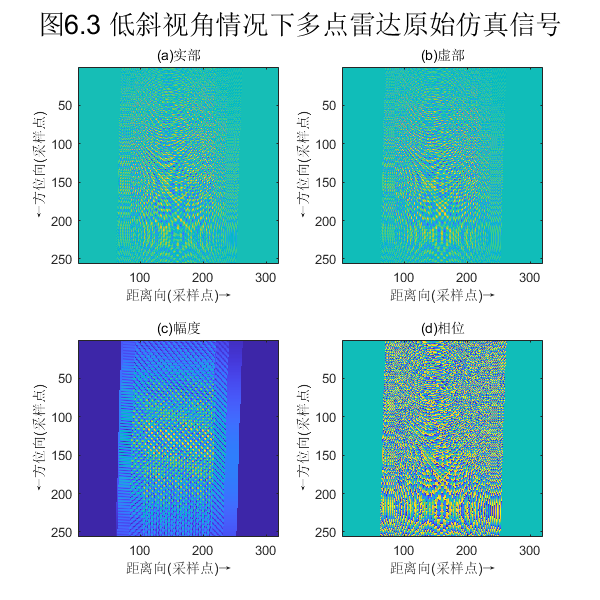

%  得到目标点的波束中心穿越时刻
Ntarget = 4;
Tar_t_eta_c = zeros(1,Ntarget);
for i = 1 : Ntarget
    DeltaX = NPosition(i,2) - NPosition(i,1)*tan(theta_r_c(1));
    Tar_t_eta_c(i) = DeltaX/Vs;
end
%  得到目标点的绝对零多普勒时刻
Tar_t_eta_o = zeros(1,Ntarget);
for i = 1 : Ntarget
    Tar_t_eta_o(i) = NPosition(i,2)/Vr;
end
%% 变量设置
%  时间变量 以景中心的零多普勒时刻作为方位向零点
t_tau = (-Trg/2:d_t_tau:Trg/2-d_t_tau) + 2*R_eta_c/c;   % 距离时间变量
t_eta = (-Taz/2:d_t_eta:Taz/2-d_t_eta) + t_eta_c(1);    % 方位时间变量
%{
t_tau = (-Nrg/2:Nrg/2-1)/Fr + 2*R_eta_c/c;              % 距离时间变量
t_eta = (-Naz/2:Naz/2-1)/Fa + t_eta_c(1);               % 方位时间变量
%}
%{
t_tau = linspace(-Nrg/2,Nrg/2-1,Nrg)/Fr + 2*R_eta_c/c;  % 距离时间变量
t_eta = linspace(-Naz/2:Naz/2-1,Naz)/Fa + t_eta_c(1);   % 方位时间变量
%}
%  长度变量
r_tau = (t_tau*c/2)*cos(theta_r_c(1));                  % 距离长度变量
%{
r_tau = ((-Trg/2:d_t_tau:Trg/2-d_t_tau)*c/2)*cos(theta_r_c(1)) + R0;
                                                        % 距离长度变量
%}                                                      
%{
r_tau = ((-Nrg/2:Nrg/2-1)*rho_r)*cos(theta_r_c(1)) + R0;% 距离长度变量
%}                                                      
%{
r_tau = (linspace(-Nrg/2,Nrg/2-1,Nrg)*rho_r)*cos(theta_r_c(1)) + R0;
                                                        % 距离长度变量
%}                                                      
%  频率变量 
f_tau = ifftshift(-Fr/2:d_f_tau:Fr/2-d_f_tau);          % 距离频率变量
f_tau = f_tau - round((f_tau-0)/Fr)*Fr;                 % 距离频率变量(可观测频率)
%{
f_tau = ifftshift((-Nrg/2:Nrg/2-1)*Fr/Nrg);             % 距离频率变量
f_tau = f_tau - round((f_tau-0)/Fr)*Fr;                 % 距离频率变量(可观测频率)
%} 
%{
f_tau = ifftshift(linspace(-Nrg/2,Nrg/2-1,Nrg)*Fr/Nrg); % 距离频率变量
f_tau = f_tau - round((f_tau-0)/Fr)*Fr;                 % 距离频率变量(可观测频率)
%}
f_eta = ifftshift(-Fa/2:d_f_eta:Fa/2-d_f_eta);          % 方位频率变量
f_eta = f_eta - round((f_eta-f_eta_c(1))/Fa)*Fa;        % 方位频率变量(可观测频率)
%{
f_eta = ifftshift((-Naz/2:Naz/2-1)*Fa/Naz);             % 方位频率变量
f_eta = f_eta - round((f_eta-f_eta_c(1))/Fa)*Fa;        % 方位频率变量(可观测频率)
%} 
%{
f_eta = ifftshift(linspace(-Naz/2,Naz/2-1,Naz)*Fa/Naz); % 脉冲频率变量
f_eta = f_eta - round((f_eta-f_eta_c(1))/Fa)*Fa;        % 方位频率变量(可观测频率)
%}
%  坐标设置 以距离时间为X轴，方位时间为Y轴
%{
[X,Y] = meshgrid(x,y)是基于向量x和向量y中包含的坐标返回二维网络坐标。
 X是一个矩阵，每一行是x的一个副本；
 Y是一个矩阵，每一列是y的一个副本；
 坐标X和Y表示的网络有length(y)个行和length(x)个列。
%}                                                                                                             
[t_tauX,t_etaY] = meshgrid(t_tau,t_eta);                % 设置距离时域-方位时域二维网络坐标
%  坐标设置 以距离长度为X轴，方位频率为Y轴                                                                                                            
[r_tauX,f_etaY] = meshgrid(r_tau,f_eta);                % 设置距离时域-方位频域二维网络坐标
%  坐标设置 以距离频率为X轴，方位频率为Y轴                                                                                                            
[f_tau_X,f_eta_Y] = meshgrid(f_tau,f_eta);              % 设置频率时域-方位频域二维网络坐标
%% 信号设置--》原始回波信号                                                        
srt = zeros(Naz,Nrg);
for i = 1 : Ntarget
    %  计算目标点的瞬时斜距
    R_eta = sqrt( NPosition(i,1)^2 +...
                  Vr^2*(t_etaY-Tar_t_eta_o(i)).^2 ); 
    %{
    R_eta = NPosition(i,1) + Vr^2*t_etaY.^2/(2*NPosition(i,1));   
    %}
    %  后向散射系数幅度
    A0 = [1,1,1,1]*exp(+1j*0);   
    %  距离向包络
    wr = (abs(t_tauX-2*R_eta/c) <= Tr/2);                               
    %{
    距离向包络为矩形窗，因此可以观察到信号幅度图在距离向是均匀的，
    但是严格的矩形窗也导致了幅度图和相位图在左右两侧均出现0值区域。
    %}
    %  方位向包络
    wa = sinc(0.886*atan(Vg*(t_etaY-Tar_t_eta_c(i))/NPosition(i,1))/theta_bw).^2;      
    %{
    方位向包络为sinc^2()的形式，因此可以观察到信号幅度图在方位向上
    中心最强，而两侧的强度以sinc^2()的形式衰减。
    %}
    %  接收信号叠加
    srt_tar = A0(i)*wr.*wa.*exp(-1j*4*pi*f0*R_eta/c)...
                          .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2); 
    %{
    srt_tar = A0(i)*wr.*wa.*exp(-1j*4*pi*R0/lambda)...
                          .*exp(-1j*pi*Ka*t_eta_Y.^2)...
                          .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2);
    %}                                                          
    srt = srt + srt_tar;  
end
%  绘图
H1 = figure();
set(H1,'position',[100,100,600,600]);                    
subplot(221),imagesc( real(srt))             
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(a)实部')
subplot(222),imagesc( imag(srt))
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(b)虚部')
subplot(223),imagesc(  abs(srt)) 
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(c)幅度')
subplot(224),imagesc(angle(srt))
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(d)相位')
sgtitle('图6.3 低斜视角情况下多点雷达原始仿真信号','Fontsize',20,'color','k')

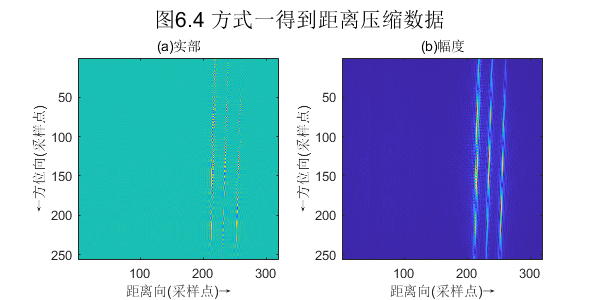

%% 信号设置--》一次距离压缩
%  变量设置
dt = Tr/Nr;                                             % 脉冲时间间隔
ttau = -Tr/2:dt:Tr/2-dt;                                % 脉冲时间变量
%{
ttau = (-Nr/2:Nr/2-1)/Fr;                               % 脉冲时间变量
%}
%{
ttau = linspace(-Nr/2,Nr/2,Nr)/Fr;                      % 脉冲时间变量
%}
df = Fr/Nrg;                                            % 脉冲频率间隔
ftau = ifftshift(-Fr/2:df:Fr/2-df);                     % 脉冲频率变量
ftau = ftau - round(ftau/Fr)*Fr;                        % 脉冲频率变量(可观测频率)
%{
ftau = ifftshift((-Nrg/2:Nrg/2-1)*Fr/Nrg);              % 脉冲频率变量
ftau = ftau - round(ftau/Fr)*Fr;                        % 脉冲频率变量(可观测频率)
%} 
%{
ftau = ifftshift(linspace(-Nrg/2,Nrg/2-1,Nrg)*Fr/Nrg);  % 脉冲频率变量
ftau = ftau - round(ftau/Fr)*Fr;                        % 脉冲频率变量(可观测频率)
%}
%  计算滤波器
%  信号变换-->方式一：复制脉冲，时间反褶后取复共轭，补零DFT得到频域匹配滤波器
%  加窗函数
window_1 = kaiser(Nr,2.5)';                             % 时域窗
Window_1 = fftshift(window_1);                          % 频域窗
hrt_1 = (abs(ttau)<=Tr/2).*exp(+1j*pi*Kr*ttau.^2);      % 复制脉冲
hrt_window_1 = Window_1.*hrt_1;                         % 加窗
Hrf_1 = repmat(fft(conj(fliplr(hrt_window_1)),Nrg,2),[Naz,1]);                        
%  信号变换-->方式二：复制脉冲，补零DFT，取复共轭得到频域匹配滤波器无时间反褶
window_2 = kaiser(Nr,2.5)';                             % 时域窗
Window_2 = fftshift(window_2);                          % 频域窗
hrt_2 = (abs(ttau)<=Tr/2).*exp(+1j*pi*Kr*ttau.^2);      % 复制脉冲
hrt_window_2 = Window_2.*hrt_2;                         % 加窗
Hrf_2 = repmat(conj(fft(hrt_window_2,Nrg,2)),[Naz,1]);                   
%  信号变换-->方式三：根据脉冲频谱特性直接在频域生成品与匹配滤波器
window_3 = kaiser(Nrg,2.5)';                            % 时域窗
Window_3 = fftshift(window_3);                          % 频域窗
Hrf_3 = (abs(ftau)<=Bw/2).*Window_3.*exp(+1j*pi*ftau.^2/Kr);  
%  匹配滤波
Srf = fft(srt,Nrg,2);
Soutf_1 = Srf.*Hrf_1;
soutt_1 = ifft(Soutf_1,Nrg,2);
Soutf_2 = Srf.*Hrf_2;
soutt_2 = ifft(Soutf_2,Nrg,2);
Soutf_3 = Srf.*Hrf_3;
soutt_3 = ifft(Soutf_3,Nrg,2);
%{
Srf = fft(srt.').';
Soutf_1 = Srf.*Hf_r1;
soutt_1 = ifft(Soutf_1.').';
Soutf_2 = Srf.*Hf_r2;
soutt_2 = ifft(Soutf_2.').';
Soutf_3 = Srf.*Hf_r3;
soutt_3 = ifft(Soutf_3.').';
%}
%  绘图
H2 = figure();
set(H2,'position',[100,100,600,300]); 
subplot(121),imagesc(real(soutt_1))
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(a)实部')
subplot(122),imagesc( abs(soutt_1))
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(b)幅度')
sgtitle('图6.4 方式一得到距离压缩数据','Fontsize',16,'color','k')

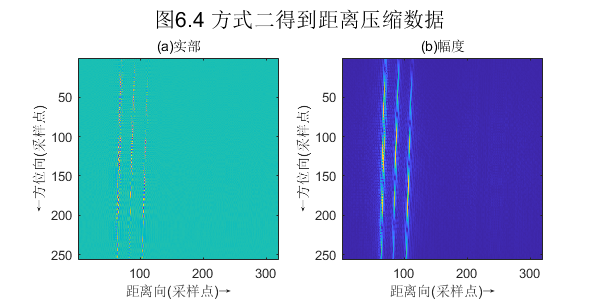

%  绘图
H3 = figure();
set(H3,'position',[100,100,600,300]); 
subplot(121),imagesc(real(soutt_2))
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(a)实部')
subplot(122),imagesc( abs(soutt_2))
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(b)幅度')
sgtitle('图6.4 方式二得到距离压缩数据','Fontsize',16,'color','k')

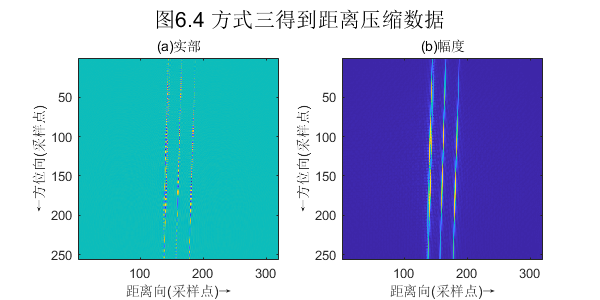

%  绘图
H4 = figure();
set(H4,'position',[100,100,600,300]); 
subplot(121),imagesc(real(soutt_3))
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(a)实部')
subplot(122),imagesc( abs(soutt_3))
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('←方位向(采样点)'),title('(b)幅度')
sgtitle('图6.4 方式三得到距离压缩数据','Fontsize',16,'color','k')

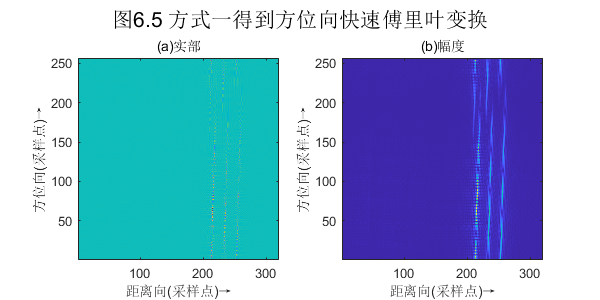

%% 信号设置--》方位向傅里叶变换
Srdf_1 = fft(soutt_1,Naz,1);
Srdf_2 = fft(soutt_2,Naz,1);
Srdf_3 = fft(soutt_3,Naz,1);
%  绘图
H5 = figure();
set(H5,'position',[100,100,600,300]); 
subplot(121),imagesc(real(Srdf_1)),set(gca,'YDir','normal')
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(a)实部')
subplot(122),imagesc( abs(Srdf_1)),set(gca,'YDir','normal')
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(b)幅度')
sgtitle('图6.5 方式一得到方位向快速傅里叶变换','Fontsize',16,'color','k')

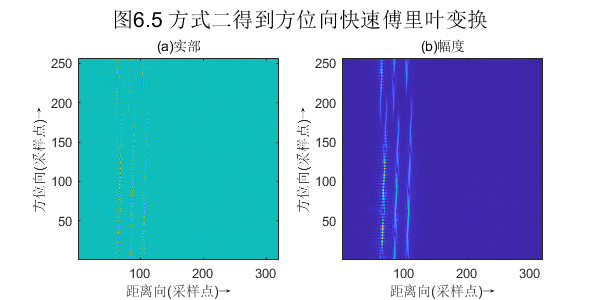

%  绘图
H6 = figure();
set(H6,'position',[100,100,600,300]); 
subplot(121),imagesc(real(Srdf_2)),set(gca,'YDir','normal')
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(a)实部')
subplot(122),imagesc( abs(Srdf_2)),set(gca,'YDir','normal')
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(b)幅度')
sgtitle('图6.5 方式二得到方位向快速傅里叶变换','Fontsize',16,'color','k')

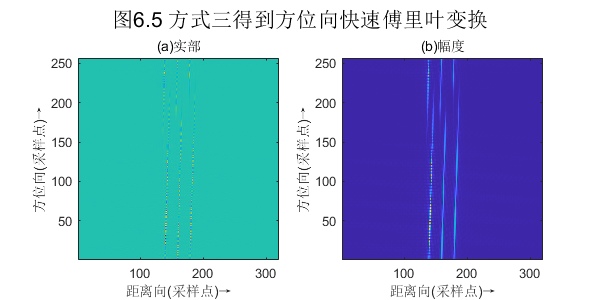

%  绘图
H7 = figure();
set(H7,'position',[100,100,600,300]); 
subplot(121),imagesc(real(Srdf_3)),set(gca,'YDir','normal')
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(a)实部')
subplot(122),imagesc( abs(Srdf_3)),set(gca,'YDir','normal')
%  axis([10 150,0 256])
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(b)幅度')
sgtitle('图6.5 方式三得到方位向快速傅里叶变换','Fontsize',16,'color','k')

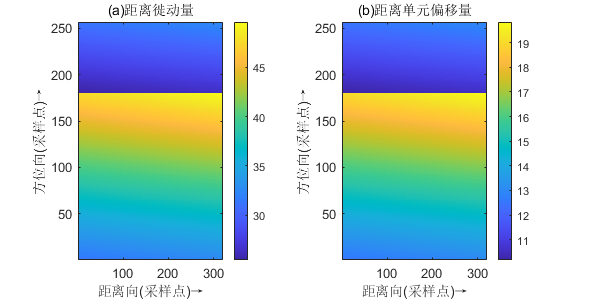

%% 信号设置--》距离徙动校正
RCM_t = lambda^2*r_tauX.*f_etaY.^2/(8*Vr^2);            % 需要校正的距离徙动量
RCM_r = RCM_t/rho_r;                                    % 将距离徙动量转换为距离单元偏移量
%  绘图
H8 = figure();
set(H8,'position',[100,300,600,300]); 
subplot(121),imagesc(RCM_t),colorbar,set(gca,'YDir','normal')
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(a)距离徙动量')
subplot(122),imagesc(RCM_r),colorbar,set(gca,'YDir','normal')
xlabel('距离向(采样点)→'),ylabel('方位向(采样点)→'),title('(b)距离单元偏移量')

x_tmp = repmat(-4:3,[16,1])

x_tmp =     -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3


x_tmp = x_tmp + repmat(((1:16)/16).',[1,8])

x_tmp =    -3.9375   -2.9375   -1.9375   -0.9375    0.0625    1.0625    2.0625    3.0625
   -3.8750   -2.8750   -1.8750   -0.8750    0.1250    1.1250    2.1250    3.1250
   -3.8125   -2.8125   -1.8125   -0.8125    0.1875    1.1875    2.1875    3.1875
   -3.7500   -2.7500   -1.7500   -0.7500    0.2500    1.2500    2.2500    3.2500
   -3.6875   -2.6875   -1.6875   -0.6875    0.3125    1.3125    2.3125    3.3125
   -3.6250   -2.6250   -1.6250   -0.6250    0.3750    1.3750    2.3750    3.3750
   -3.5625   -2.5625   -1.5625   -0.5625    0.4375    1.4375    2.4375    3.4375
   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000
   -3.4375   -2.4375   -1.4375   -0.4375    0.5625    1.5625    2.5625    3.5625
   -3.3750   -2.3750   -1.3750   -0.3750    0.6250    1.6250    2.6250    3.6250


hx = sinc(x_tmp)

hx =    -0.0158    0.0211   -0.0321    0.0662    0.9936   -0.0584    0.0301   -0.0203
   -0.0314    0.0424   -0.0650    0.1392    0.9745   -0.1083    0.0573   -0.0390
   -0.0464    0.0629   -0.0976    0.2177    0.9432   -0.1489    0.0808   -0.0555
   -0.0600    0.0818   -0.1286    0.3001    0.9003   -0.1801    0.1000   -0.0693
   -0.0718    0.0985   -0.1568    0.3850    0.8469   -0.2016    0.1144   -0.0799
   -0.0811    0.1120   -0.1810    0.4705    0.7842   -0.2139    0.1238   -0.0871
   -0.0876    0.1218   -0.1998    0.5550    0.7136   -0.2172    0.1281   -0.0908
   -0.0909    0.1273   -0.2122    0.6366    0.6366   -0.2122    0.1273   -0.0909
   -0.0908    0.1281   -0.2172    0.7136    0.5550   -0.1998    0.1218   -0.0876
   -0.0871    0.1238   -0.2139    0.7842    0.4705   -0.1810    0.1120   -0.0811


x_tmp16 = x_tmp.*16

x_tmp16 =    -63   -47   -31   -15     1    17    33    49
   -62   -46   -30   -14     2    18    34    50
   -61   -45   -29   -13     3    19    35    51
   -60   -44   -28   -12     4    20    36    52
   -59   -43   -27   -11     5    21    37    53
   -58   -42   -26   -10     6    22    38    54
   -57   -41   -25    -9     7    23    39    55
   -56   -40   -24    -8     8    24    40    56
   -55   -39   -23    -7     9    25    41    57
   -54   -38   -22    -6    10    26    42    58


x_tmp16 = round(x_tmp16 + 16*8/2)

x_tmp16 =      1    17    33    49    65    81    97   113
     2    18    34    50    66    82    98   114
     3    19    35    51    67    83    99   115
     4    20    36    52    68    84   100   116
     5    21    37    53    69    85   101   117
     6    22    38    54    70    86   102   118
     7    23    39    55    71    87   103   119
     8    24    40    56    72    88   104   120
     9    25    41    57    73    89   105   121
    10    26    42    58    74    90   106   122


kwin = repmat(kaiser(16*8,2.5).',[16,1])

kwin =     0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113    0.4269    0.4425    0.4582    0.4739    0.4896    0.5052    0.5209    0.5365    0.5520    0.5675    0.5829    0.5982    0.6134    0.6284    0.6434    0.6581    0.6727    0.6872    0.7014    0.7155    0.7293    0.7430    0.7564    0.7695    0.7824    0.7950    0.8073    0.8193    0.8310    0.8424    0.8535    0.8642    0.8746    0.8846    0.8943    0.9036    0.9125    0.9210    0.9291    0.9368    0.9441    0.9510
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113    0.4269    0.4425    0.4582    0.4739    0.4896    0.5052    0.5209    0.5365    0.5520    0.5675    0.5829    0.5982    0.6134    0.6284    0.6434    0.6581    0.6727    0.6872    0.7014    0.7155    0.7293    0.7430    0.7564    0.7695    0.7824    0.7950    0.8073    0.8193    0.8310    0.8424    0.8535    0.8642    0.8746    0.8846    0.8943    0.9036    0.9125    0.9210    0.9291    0.9368    0.9441  

kwin(x_tmp16)

ans =     0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113
    0.3040    0.3190    0.3341    0.3494    0.3647    0.3802    0.3957    0.4113


hx = kwin(x_tmp16).*hx

hx =    -0.0048    0.0067   -0.0107    0.0231    0.3624   -0.0222    0.0119   -0.0083
   -0.0096    0.0135   -0.0217    0.0486    0.3554   -0.0412    0.0227   -0.0160
   -0.0141    0.0201   -0.0326    0.0760    0.3440   -0.0566    0.0320   -0.0228
   -0.0182    0.0261   -0.0430    0.1049    0.3284   -0.0685    0.0396   -0.0285
   -0.0218    0.0314   -0.0524    0.1345    0.3089   -0.0767    0.0453   -0.0329
   -0.0247    0.0357   -0.0605    0.1644    0.2860   -0.0813    0.0490   -0.0358
   -0.0266    0.0389   -0.0668    0.1939    0.2603   -0.0826    0.0507   -0.0374
   -0.0276    0.0406   -0.0709    0.2224    0.2322   -0.0807    0.0504   -0.0374
   -0.0276    0.0409   -0.0726    0.2493    0.2024   -0.0760    0.0482   -0.0360
   -0.0265    0.0395   -0.0715    0.2740    0.1716   -0.0688    0.0443   -0.0334


sum(hx,2)

ans =     0.3581
    0.3518
    0.3460
    0.3408
    0.3364
    0.3329
    0.3304
    0.3290
    0.3286
    0.3293


hx = hx./repmat(sum(hx,2),[1,8])

hx =    -0.0134    0.0188   -0.0299    0.0646    1.0119   -0.0620    0.0333   -0.0233
   -0.0272    0.0384   -0.0617    0.1383    1.0103   -0.1170    0.0645   -0.0456
   -0.0408    0.0580   -0.0942    0.2198    0.9943   -0.1636    0.0925   -0.0660
   -0.0535    0.0766   -0.1261    0.3077    0.9636   -0.2009    0.1162   -0.0836
   -0.0649    0.0934   -0.1558    0.3999    0.9184   -0.2279    0.1346   -0.0977
   -0.0741    0.1074   -0.1816    0.4939    0.8592   -0.2443    0.1472   -0.1076
   -0.0806    0.1176   -0.2021    0.5869    0.7877   -0.2499    0.1534   -0.1130
   -0.0840    0.1235   -0.2155    0.6761    0.7058   -0.2452    0.1531   -0.1137
   -0.0840    0.1243   -0.2208    0.7586    0.6160   -0.2311    0.1467   -0.1097
   -0.0804    0.1199   -0.2170    0.8320    0.5211   -0.2089    0.1346   -0.1013
